# Linear Systems- Lab 2

name: Zhu Chenhao

HDU ID: 22320630

ITMO ID: 375462

Email: 22320630@hdu.edu.cn

 Case 4. Mass-Spring-Damper system with free base

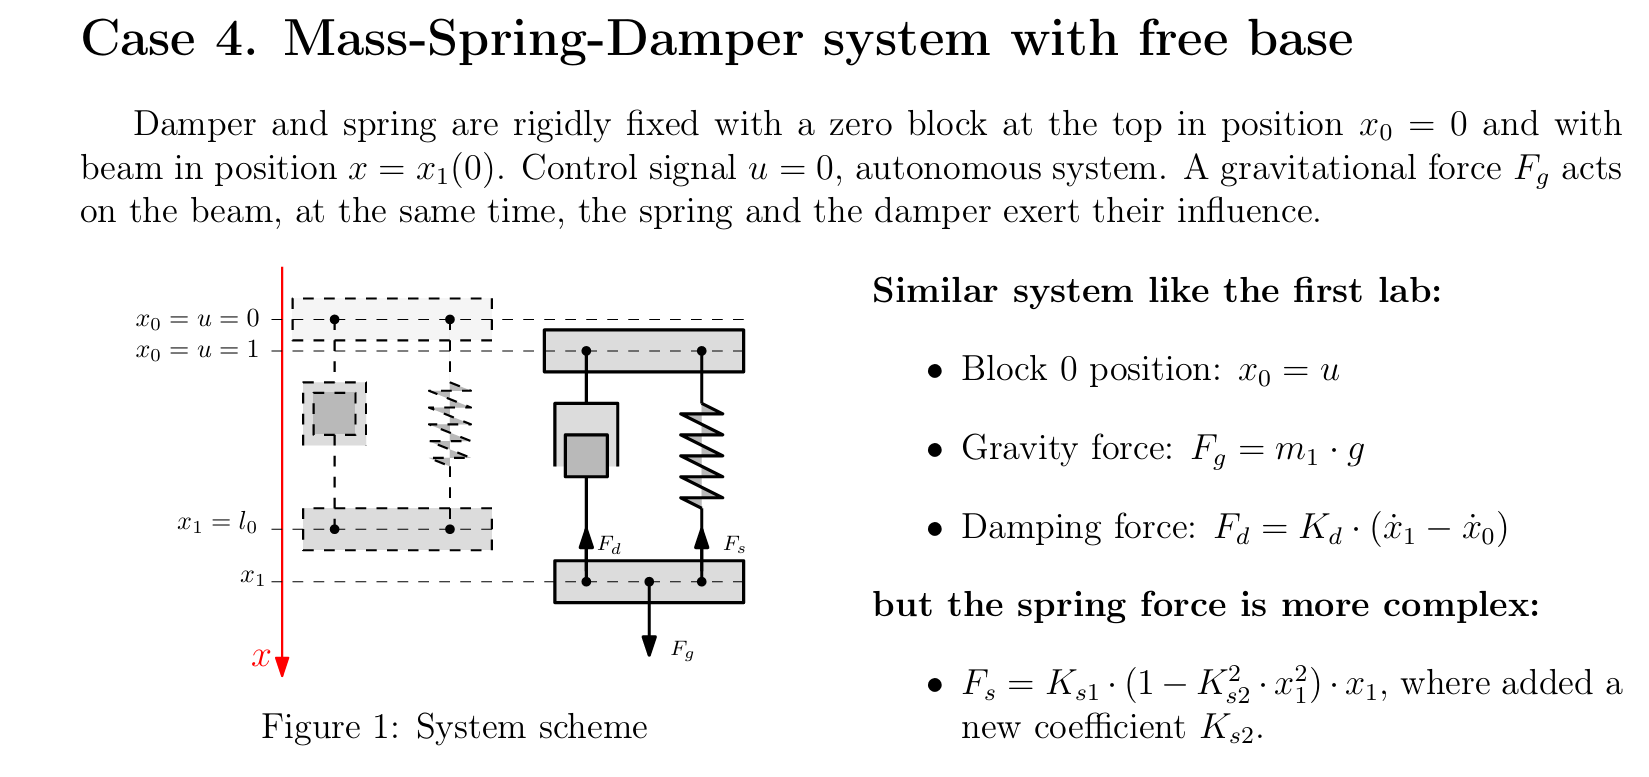

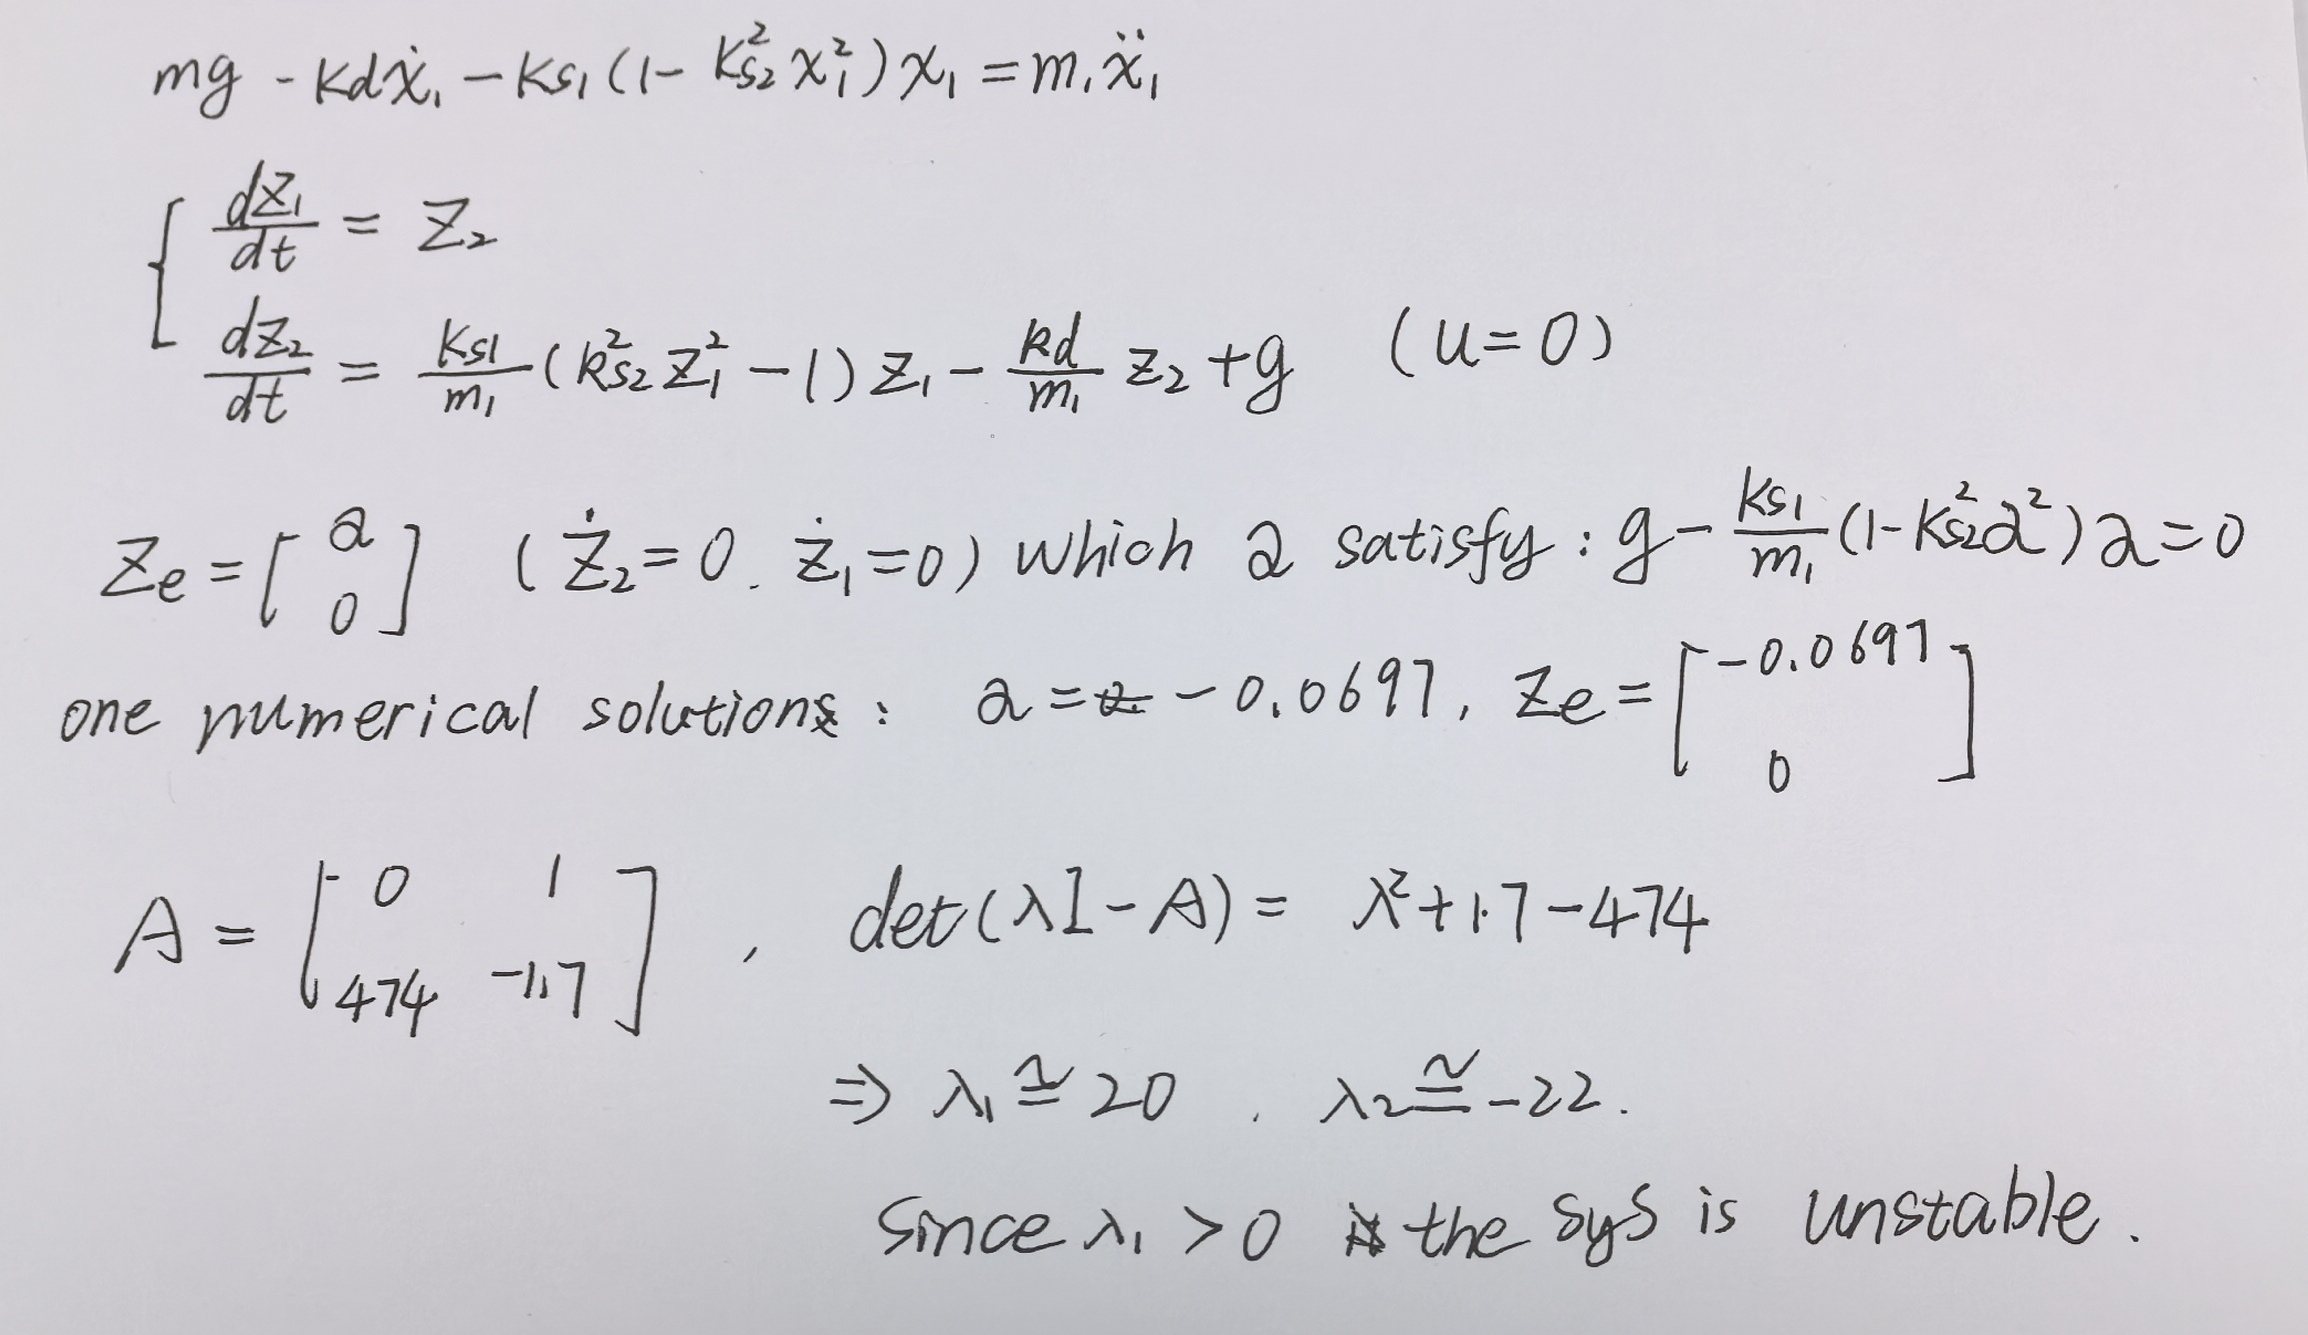

hwc = hwc_connect('https://dss2025.hdu.vedyakov.com');

Connection established


task = hwc.get_task(2);

Kd=task.parameters.Kd;
Ks1=task.parameters.Ks1;
Ks2=task.parameters.Ks2;
m1=task.parameters.m1;
g=task.parameters.g;



%% Task 1: Find equilibrium points
[z1_eq, z2_eq] = find_equilibrium(m1, g, Ks1, Ks2);
fprintf('Equilibrium point:\n');

Equilibrium point:


fprintf('  z1 = %.4f\n', z1_eq);

  z1 = -0.0697


fprintf('  z2 = %.4f\n', z2_eq);

  z2 = 0.0000



%% Task 2: Compute Jacobian and check stability
[J, A_lin] = compute_jacobian(z1_eq, m1, Kd, Ks1, Ks2);
fprintf('\nJacobian matrix:\n');


Jacobian matrix:


disp(J);

         0    1.0000
  474.5342   -1.7063




is_stable = check_stability(A_lin);
fprintf('System is stable: %d\n', is_stable);

System is stable: 0


p=[Ks2^2 0 -1 m1*g/Ks1];
roots(p)

ans =   -0.0697 + 0.0000i
   0.0348 + 0.0537i
   0.0348 - 0.0537i


%% Task 3: Simulate nonlinear and linear systems
tspan = [0 0.25];
z0 = [z1_eq+0.1; 0];

% Input signals
% Case 1: Step input u = 1(t)
u_step = @(t) 1*(t >= 0);

% Case 2: Ramp input u = 2t
u_ramp = @(t) 2*t;

% Simulate nonlinear system with step input
[t_nl_step, z_nl_step] = ode45(@(t,z) mass_spring_damper(t, z, m1, g, Kd, Ks1, Ks2), tspan, z0);


% Simulate linearized system with step input
A = J;
B = [0; 1/m1];
C = [1 0];
D = 0;

sys_lin = ss(A, B, C, D);
t_lin_step = linspace(tspan(1), tspan(2), 100);
y_lin_step = lsim(sys_lin, u_step(t_lin_step), t_lin_step, z0);

% Simulate nonlinear system with ramp input
[t_nl_ramp, z_nl_ramp] = ode45(@(t,z) mass_spring_damper(t, z, m1, g, Kd, Ks1, Ks2), tspan, z0);

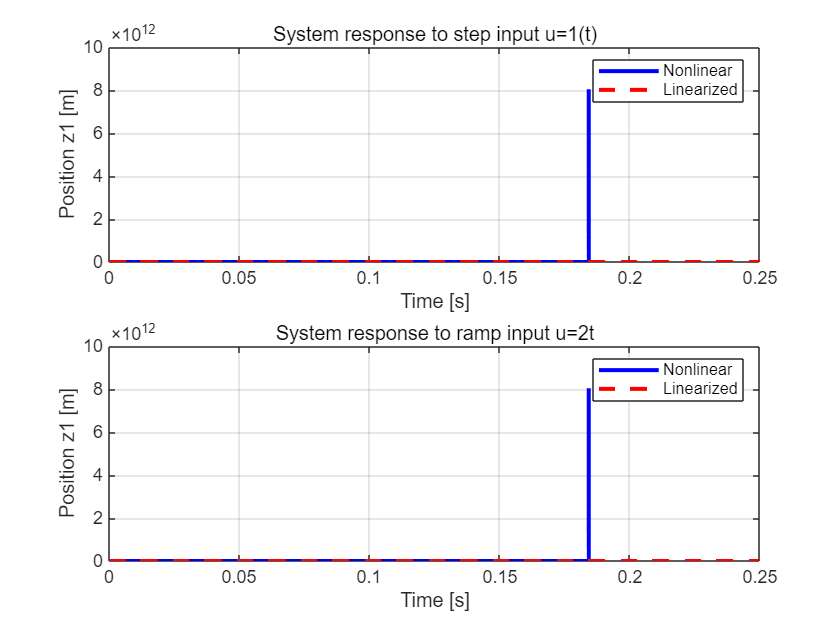


% Simulate linearized system with ramp input
y_lin_ramp = lsim(sys_lin, u_ramp(t_lin_step), t_lin_step, z0);

%% Plot results
figure;

% Step input response
subplot(2,1,1);
plot(t_nl_step, z_nl_step(:,1), 'b-', 'LineWidth', 2); hold on;
plot(t_lin_step, y_lin_step, 'r--', 'LineWidth', 2);
xlabel('Time [s]');
ylabel('Position z1 [m]');
title('System response to step input u=1(t)');
legend('Nonlinear', 'Linearized');
grid on;

% Ramp input response
subplot(2,1,2);
plot(t_nl_ramp, z_nl_ramp(:,1), 'b-', 'LineWidth', 2); hold on;
plot(t_lin_step, y_lin_ramp, 'r--', 'LineWidth', 2);
xlabel('Time [s]');
ylabel('Position z1 [m]');
title('System response to ramp input u=2t');
legend('Nonlinear', 'Linearized');
grid on;

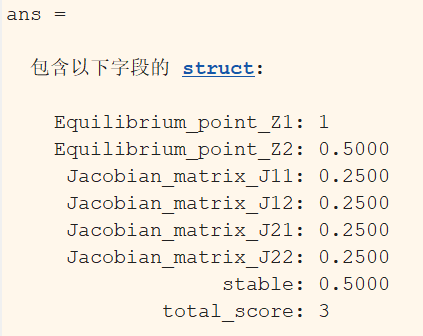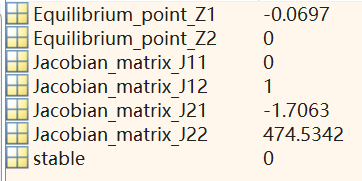

syms z1 z2
a=[z1 z2];
f=[z2;g-Ks1/m1*(1-Ks2^2*z1^2)*z1-Kd/m1*z2];
x = jacobian(f,a);
b=[z1_eq 0];
J = subs(x,a,b);
J = eval(J)

J =          0    1.0000
  474.5342   -1.7063




%%
task.answers.stable=0;
task.answers.Equilibrium_point_Z1=z1_eq;
task.answers.Equilibrium_point_Z2=0;
task.answers.Jacobian_matrix_J11=0;
task.answers.Jacobian_matrix_J12=1;
task.answers.Jacobian_matrix_J21=J(2,2);
task.answers.Jacobian_matrix_J22=J(2,1);

eig(J)

ans =    20.9474
  -22.6536


function dz = mass_spring_damper(t, z, m1, g, Kd, Ks1, Ks2)
    % State vector z = [z1; z2] = [x1; x1_dot]
    z1 = z(1);
    z2 = z(2);
    % Spring force (nonlinear)
    Fs = Ks1 * (1 - Ks2^2 * z1^2) * z1;
    % Damping force
    Fd = Kd * z2;  % since x0_dot = 0 (fixed base)
    % Gravity force
    Fg = m1 * g;
    % Dynamics
    dz1 = z2;
    dz2 = (Fg - Fs - Fd) / m1;
    dz = [dz1; dz2];
end

function [z1_eq, z2_eq] = find_equilibrium(m1, g, Ks1, Ks2)
    % At equilibrium, z2 = 0 and dz2 = 0
    % So we solve: Fg = Fs => m1*g = Ks1*(1 - Ks2^2*z1^2)*z1
    
    % Rearrange: Ks1*Ks2^2*z1^3 - Ks1*z1 + m1*g = 0
    coeffs = [Ks1*Ks2^2, 0, -Ks1, m1*g];
    solutions = roots(coeffs);
    
    % Find real solutions
    real_solutions = solutions(imag(solutions) == 0);
    
    % Return the solution closest to zero
    [~, idx] = min(abs(real_solutions));
    z1_eq = real_solutions(idx);
    z2_eq = 0;  % equilibrium condition
end

function [J, A_lin] = compute_jacobian(z1_eq, m1, Kd, Ks1, Ks2)
    % Jacobian matrix elements
    J11 = 0;
    J12 = 1;
    
    % Derivative of Fs with respect to z1
    dFs_dz1 = Ks1 * (1 - 3*Ks2^2*z1_eq^2);
    
    J21 = -dFs_dz1 / m1;
    J22 = -Kd / m1;
    
    J = [J11, J12;
         J21, J22];
    
    % Linearized system matrix
    A_lin = J;
end

function is_stable = check_stability(A_lin)
    % Check if all eigenvalues have negative real parts
    eigs = eig(A_lin);
    is_stable = all(real(eigs) < 0);
end